## **Uniform**

For each distribution, anwser the following questions:

- Is the RV discrete or continuous?

- What is the domain of the RV's PDF or PMF ?

- Describe the parameters of the distribution: how many are they? What values can they take?

- Give one example of real world phenomenon or data that could be modelled using the distribution.

and complete the following tasks:

- Plot the (theoretical) PDF (for contiuous RVs) or PMF (for discrete RVs) and the mean

- Draw a sample of $S=1000$ random outcomes.

- Plot the empirical PDF or PMF of these samples on the same plot created in task 1.

- Plot the (theoretical) CDF

- Plot the empirical CDF of the samples generated in task 2 on the same plot created in task 4.

- Use a Q-Q plot to show the similarity between empirical and theoretical quantiles.

Exponential distribution is a continuous one.

Output domain is > 0

One parameter: $\mu$ = standard deviation. Standard is 1

Examples include decay curves

pd = makedist('Exponential', 'mu', 3)

pd =   ExponentialDistribution

  Exponential distribution
    mu = 3


outcomes = 0:0.1:20;
exp_pdf = pdf(pd, outcomes)

exp_pdf =     0.3333    0.3224    0.3118    0.3016    0.2917    0.2822    0.2729    0.2640    0.2553    0.2469    0.2388    0.2310    0.2234    0.2161    0.2090    0.2022    0.1955    0.1891    0.1829    0.1769    0.1711    0.1655    0.1601    0.1549    0.1498    0.1449    0.1401    0.1355    0.1311    0.1268    0.1226    0.1186    0.1147    0.1110    0.1073    0.1038    0.1004    0.0971    0.0939    0.0908    0.0879    0.0850    0.0822    0.0795    0.0769    0.0744    0.0719    0.0696    0.0673    0.0651


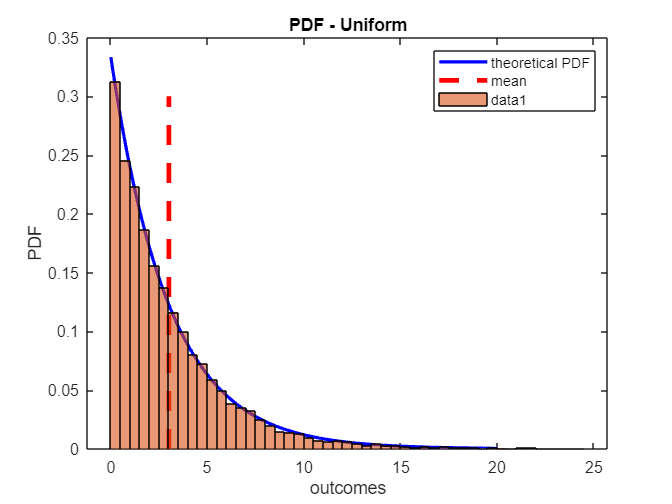

% Create small and large samples
sample = random(pd,1,10000);

% Generate plot data
clf; % clear the figure
plot(outcomes, exp_pdf, 'b', 'LineWidth', 2)
hold on
exp_mean = mean(pd); % Let's plot the distribution mean
line([exp_mean,exp_mean],[0,0.3], 'LineStyle', '--', 'Linewidth', 3,'Color','red');
legend('theoretical PDF', 'mean', 'Location','northeast')
title('PDF - Uniform') % title for plot
xlabel('outcomes') % x-axis label
ylabel('PDF') % y-axis label

exp_epmf = histogram(sample, 'normalization', 'pdf'); % correctly normalised

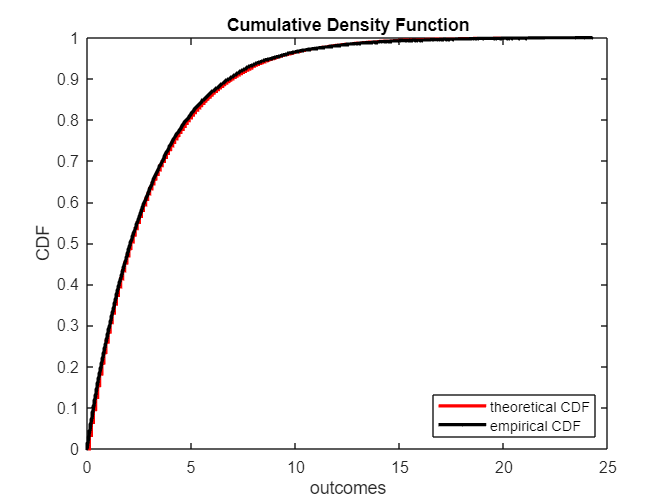

% Create cumulative density function
exp_cdf = cdf(pd, outcomes);

clf % clear the plot
stairs(outcomes, exp_cdf, '-r', 'LineWidth', 2)
hold on
legend('theoretical CDF', 'Location','southeast')
title('Cumulative Density Function') % title for plot
xlabel('outcomes') % x-axis label
ylabel('CDF') % y-axis label

[exp_ecdf, x] = ecdf(sample);
stairs(x, exp_ecdf, '.-k', 'LineWidth',2)
legend('theoretical CDF','empirical CDF')

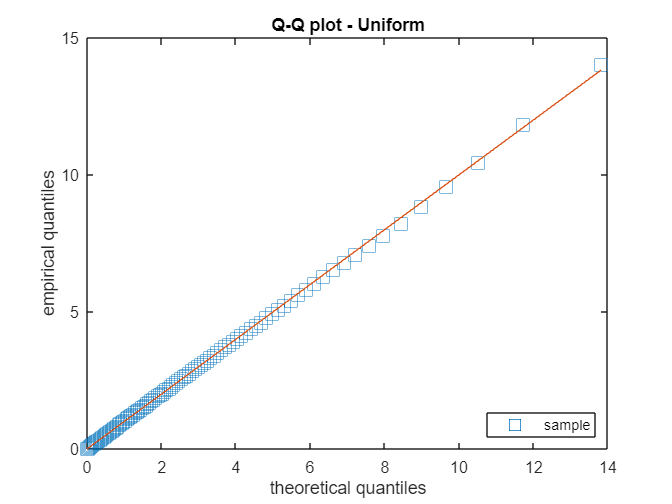

% evaluate at more points within 0 and 1
clf
pp = 0: 0.01: 1;
theor_q = icdf(pd, pp);
empir_q = quantile(sample, pp);
plot(theor_q, empir_q, 's', 'MarkerSize', 10)
hold on
plot(theor_q, theor_q, '-','HandleVisibility','off')
legend('sample', 'Location','southeast')
title('Q-Q plot - Uniform') % title for plot
xlabel('theoretical quantiles') % x-axis label
ylabel('empirical quantiles') % y-axis label